% HW 9

clc, clear; close all;

% P-10.2
% H(z) = 1/(1 - 0.9z^-1 + 0.9z^-2)
b = [1];
a = [1 -0.9 0.9];
[R,P,Z] = residuez(b,a)

R =    0.5000 - 0.2694i
   0.5000 + 0.2694i


P =    0.4500 + 0.8352i
   0.4500 - 0.8352i



Z =

     []



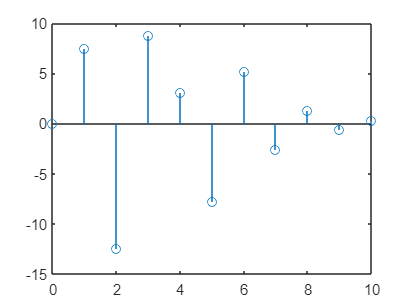

% P-10.4
clc, clear; close all;

 n = 0:10;
 x = (15*(-0.5).^(n-1)).*heaviside(n-1) - (10*(-0.5).^(n-2)).*heaviside(n-2) + (15*(-0.5).^(n-4)).*heaviside(n-4) - (5*(-0.5).^(n-5)).*heaviside(n-5);
 stem(n,x)

% P-10.10
clc, clear; close all;

% H(z) = 1/(1 + 0.8z^-2)
% x[n] = 5delta[n] + 2.5delta[n-1] + 4delta[n-2] + 2delta[n-3]
b = [1];
a = [1 0 0.8];
x = [5 2.5 4 2];
y = filter(b,a,x)

y =     5.0000    2.5000         0         0


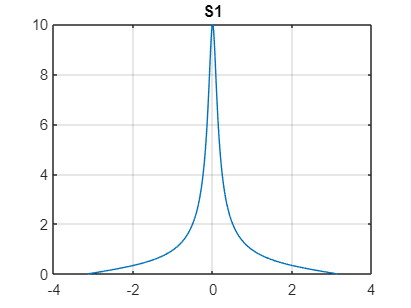

% P-10.17
clc, clear; close all;

w = -pi:0.01:pi;
% y[n] = 0.9[n-1] + (1/2)x[n] + (1/2)x[n-1]
H1 = freqz([1/2 1/2],[1 -0.9],w);
plot(w,abs(H1)); grid; title('S1')

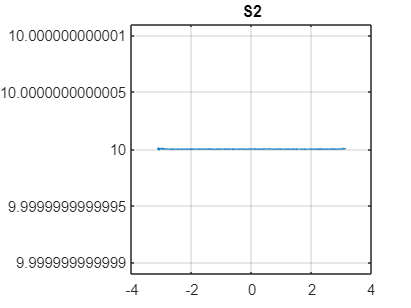


H2 = freqz([9 10],[1 0.9],w);
plot(w,abs(H2)); grid; title('S2')

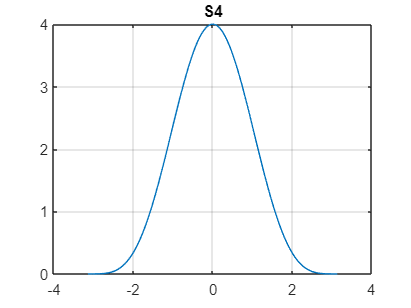


H4 = freqz([1/4 1 3/2 1 1/4],[1],w);
plot(w,abs(H4)); grid; title('S4')

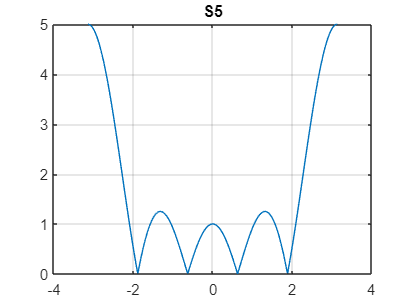


H5 = freqz([1 -1 1 -1 1],[1],w);
plot(w,abs(H5)); grid; title('S5')

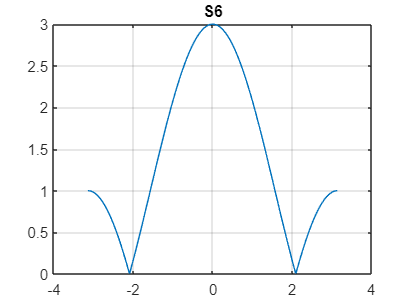


H6 = freqz([1 1 1],[1],w);
plot(w,abs(H6)); grid; title('S6')

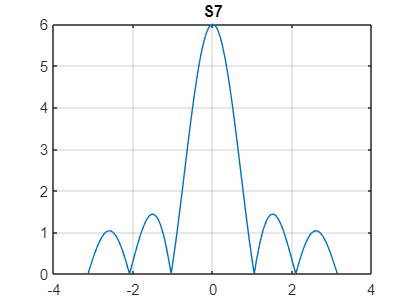


H7 = freqz([1 1 1 1 1 1],[1],w);
plot(w,abs(H7)); grid; title('S7')

% 9)
clc, clear; close all;

% H(z) = (z^-1)/(1 - 0.9z^-1 + 0.9z^-2)
b = [0 1];
a = [3 -4 1];
[R,P,Z] = residuez(b,a)

R =     0.5000
   -0.5000


P =     1.0000
    0.3333



Z =

     []



% [r,p,k] = residue(b,a) finds the residues, poles, and direct term of a Partial 
% Fraction Expansion of the ratio of two polynomials, where the expansion is of 
% the form

% [ro,po,ko] = residuez(bi,ai) finds the residues, poles, and direct terms of a 
% partial fraction expansion of the ratio of numerator and denominator polynomials,
% b and a.

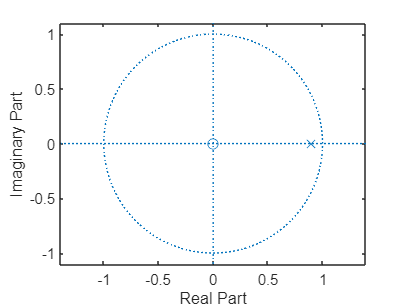

% 10)
clc, clear; close all;

% H(z) = 1/(1 - 0.9z^-1)
B = [1];
A = [1 -0.9];
zplane(B, A)

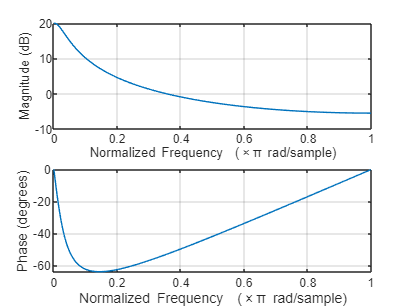


% y[n] = 0.9y[n-1] + x[n]
w = -pi:0.01:pi;
% H = freqz([1],[1 -0.9],w)
freqz([1],[1 -0.9]);

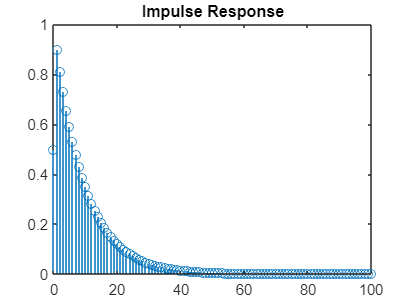

% plot(w,abs(H)); grid; title('|𝐻(𝑒𝑗𝜔̂)|')
% plot(w,angle(H)); grid; title('<𝐻(𝑒𝑗𝜔̂)')

% [h,w] = freqz(b,a,n) returns the n-point frequency response vector h and the 
% corresponding angular frequency vector w for the digital filter with transfer 
% function coefficients stored in b and a.

% h[n] = ((0.9)^n)u[n]
 n = 0:100;
 x = ((0.9).^(n)).*heaviside(n);
 stem(n,x); title("Impulse Response")